format long
syms P(w) E(w) f(w) f_d(w)

% accuracy value for the function
threshold = 10^-8;

% generator function and its derrivative
P(w) = 100*(1-exp(-0.56*w));

% energy dissipated function
E(w) = w^2 - 5*w + 30;

% starting points and roots
roots = [];
x_k = [0, 8];

% the total energy function
f(w) = P-E

$$f(w) = 5\,w-100\,{\mathrm{e}}^{-\frac{14\,w}{25}}-w^{2}+70$$

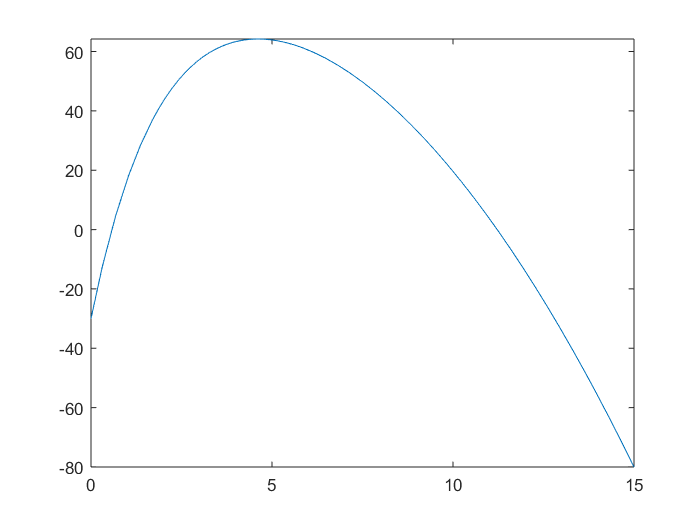

f_d(w) = diff(f);

fplot(f(w), [0,15])


% find both possible roots for the functions
for i=1:length(x_k)
    % loop through the function using newtons method to get roots, stop
    % when its less than the threshold
    while abs(f(x_k(i))) > threshold
        x_k1 = x_k(i) - f(x_k(i))/f_d(x_k(i));
        x_k(i) = x_k1;
    end
    roots = [roots, x_k1];
end

roots = double(roots)

roots =    0.573322845282703  11.221433847446772


% in Hz
vpa(roots*1000)

$$ans = \left(\begin{array}{cc} 573.32284528270270129723940044641 & 11221.433847446771324030123651028 \end{array}\right)$$